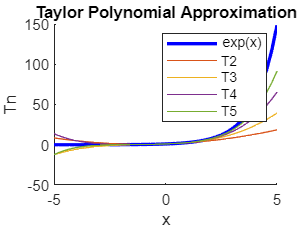

syms x f(x) Tn
f(x) = sym(exp(x)); % Define the function
n = 5;

% Calculate
Tn = 0;
% Add T0
Tn = Tn + subs(f, x, 0);
f(x) = diff(f);
% Add T1
Tn = Tn + subs(f, x, 0) * x;
f(x) = diff(f);
% Initialize
fact = 1;
figure; % Open a new figure
hold on; % Enable hold to plot all iterations on the same graph
k=5;
% plot e^x
fplot(f, [-k, k], 'b', 'LineWidth', 2); % Plot e^x in blue

for i = 2:n
    fact = fact * i;
    c = subs(f, x, 0) / fact;
    Tn = Tn + c * x^i;
    plot_handle = fplot(Tn, [-k, k]); % Plot Tn
    set(plot_handle, 'DisplayName', ['T' num2str(i)]); % Set display name for legend
    f(x) = diff(f);
end
legend('show'); % Show legend
hold off; % Release hold

xlabel('x');
ylabel('Tn');
title('Taylor Polynomial Approximation');

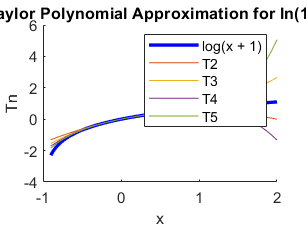

clear;
syms x f(x) Tn
f(x) = log(1 + x); % Define the function
n = 5;

% Plot the function ln(1+x)
figure; % Open a new figure
hold on; % Enable hold to plot multiple functions on the same graph
fplot(f, [-0.9, 2], 'b', 'LineWidth', 2); % Plot ln(1+x) in blue
xlabel('x');
ylabel('f(x)');
title('Plot of ln(1+x)');

% Calculate Taylor polynomial
Tn = 0;
% Add T0
Tn = Tn + subs(f, x, 0);
f(x) = diff(f);
% Add T1
Tn = Tn + subs(f, x, 0) * x;
f(x) = diff(f);
% Initialize
fact = 1;
for i = 2:n
    fact = fact * i;
    c = subs(f, x, 0) / fact;
    Tn = Tn + c * x^i;
    plot_handle = fplot(Tn, [-0.9, 2]); % Plot Tn
    set(plot_handle, 'DisplayName', ['T' num2str(i)]); % Set display name for legend
    f(x) = diff(f);
end
legend('show'); % Show legend
hold off; % Release hold

xlabel('x');
ylabel('Tn');
title('Taylor Polynomial Approximation for ln(1+x)');